# Instantiating some filters and images

% creating images with different features
im_size = 51;

% horizontal bar
img_hor = ones(im_size,im_size);
img_hor(10:20,:) = 50;
img_hor = img_hor + rand(im_size,im_size);

%vertical bar
img_ver = ones(im_size,im_size);
img_ver(:,10:20) = 50;
img_ver = img_ver + rand(im_size,im_size);

img_dot = ones(im_size,im_size);
r = 10;
row = 26;
col = 26;

[rr, cc] = ndgrid(1:size(img_dot,1), 1:size(img_dot,2));
mask = (rr - row).^2 + (cc - col).^2 <= r^2;
idx = find(mask);
img_dot(idx) = 50;
img_dot = img_dot + rand(im_size,im_size);

%create filters of differing orientation 

fil_hor = [1,1,1;0,0,0;-1,-1,-1;];

fil_ver = fil_hor';

fil_dia = [-2 -1 0;-1 0 1;0 1 2];


# Convolution includes elementwise multiplication and summation

![caption](conv.png)

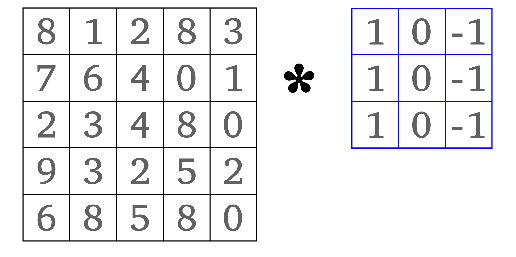

Img= imread("conv.png");
figure(),imshow(Img);


disp('#################################################')

#################################################



mat=[0,10,20;0,10,20;0,10,20;]

mat =      0    10    20
     0    10    20
     0    10    20


disp(fil_ver)

     1     0    -1
     1     0    -1
     1     0    -1



disp('the conv2d is: ')

the conv2d is: 


single_pix_conv = conv2(mat,fil_ver,'valid')

single_pix_conv = 60


disp('#################################################')

#################################################


disp("Elementwise multiplication of the flipped filter")

Elementwise multiplication of the flipped filter


element_wise = mat.*fliplr(fil_ver)

element_wise =      0     0    20
     0     0    20
     0     0    20



disp("summing all up:")

summing all up:


single_pix = sum(element_wise,'all')

single_pix = 60

# Padding

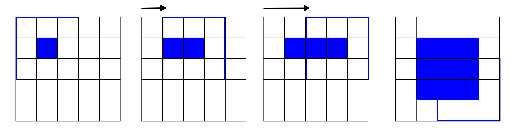


Img= imread("kernelshift.png");
figure(),imshow(Img);

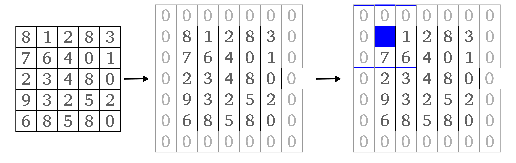



Img= imread("padding.png");
figure(),imshow(Img);


figure(),

im2 = img_dot + 30 %otherwise the padding artifact is too small. 

im2 =    31.9880   31.1412   31.4959   31.2006   31.3681   31.6100   31.3798   31.6320   31.6501   31.0372   31.7395   31.5260   31.8850   31.6629   31.8518   31.3725   31.8625   31.7028   31.8378   31.1635   31.0609   31.6795   31.9515   31.3563   31.7395   31.1886   31.1535   31.2165   31.7391   31.7065   31.6522   31.1866   31.3562   31.6662   31.0871   31.5358   31.2879   31.6443   31.6539   31.1499   31.0736   31.9263   31.1960   31.2268   31.6374   31.3097   31.6875   31.8775   31.6865   31.5568
   31.3041   31.1065   31.9248   31.9470   31.2234   31.2078   31.3067   31.7655   31.6354   31.8094   31.0968   31.4061   31.2384   31.6256   31.4658   31.7000   31.6857   31.4958   31.4609   31.5040   31.2499   31.5204   31.9569   31.0036   31.1296   31.7166   31.3244   31.9222   31.3998   31.2296   31.2818   31.4368   31.4966   31.6114   31.0374   31.4020   31.4660   31.0934   31.6165   31.4927   31.3213   31.9850   31.5554   31.7429   31.3101   31.7884   31.9318   31.7742   31.6775   

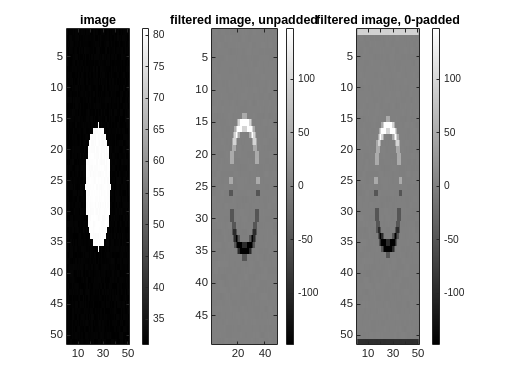

subplot(1,3,1),imagesc(im2),colormap(gray),colorbar
title('image')
subplot(1,3,2),imagesc(conv2(im2,fil_hor,'valid')),colormap(gray),colorbar
title('filtered image, unpadded')
subplot(1,3,3),imagesc(conv2(im2,fil_hor,'same')),colormap(gray),colorbar
title('filtered image, 0-padded')

# Applying different filters on images

fig = figure()

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1928 746 624 468]
       Units: 'pixels'

  Show all properties


fig.Name = 'Vertical filter applied to all images';
subplot(3,3,1),imagesc(img_hor),colormap(gray),colorbar
subplot(3,3,2),imagesc(img_ver),colormap(gray),colorbar
subplot(3,3,3),imagesc(img_dot),colormap(gray),colorbar

subplot(3,3,4),imagesc(fil_ver),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.2134 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.0534 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


subplot(3,3,5),imagesc(fil_ver),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4108 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4108 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4108 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


subplot(3,3,6),imagesc(fil_ver),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.4096 0.2134 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.4096 0.0534 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


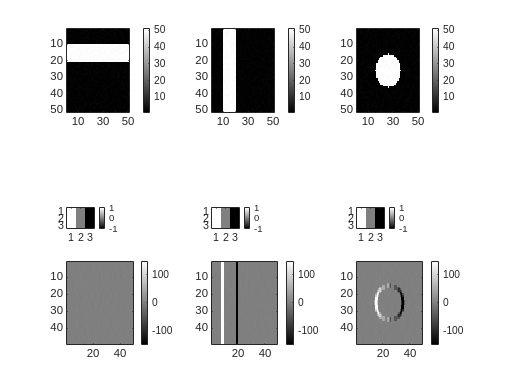


subplot(3,3,7),imagesc(conv2(img_hor,fil_ver,'valid')), colormap(gray),colorbar,caxis([-150 150])
subplot(3,3,8),imagesc(conv2(img_ver,fil_ver,'valid')), colormap(gray),colorbar,caxis([-150 150])
subplot(3,3,9),imagesc(conv2(img_dot,fil_ver,'valid')), colormap(gray),colorbar,caxis([-150 150])


%Applying the vertical filter to all images
fig = figure()

fig =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1928 746 624 468]
       Units: 'pixels'

  Show all properties


fig.Name = 'Vertical filter applied to all images';
subplot(3,3,1),imagesc(img_hor),colormap(gray),colorbar
subplot(3,3,2),imagesc(img_ver),colormap(gray),colorbar
subplot(3,3,3),imagesc(img_dot),colormap(gray),colorbar

subplot(3,3,4),imagesc(fil_hor),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.2134 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.0534 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


subplot(3,3,5),imagesc(fil_hor),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4108 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4108 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.4108 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


subplot(3,3,6),imagesc(fil_hor),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.4096 0.2134 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.4096 0.0534 0.2157]
            Units: 'normalized'

  Show all properties


ax =   Axes with properties:

             XLim: [0.5000 3.5000]
             YLim: [0.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.6916 0.4096 0.0534 0.0539]
            Units: 'normalized'

  Show all properties


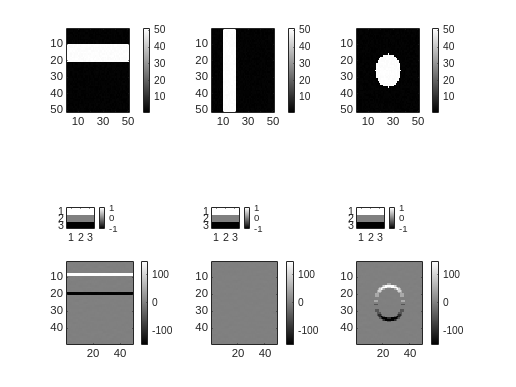


subplot(3,3,7),imagesc(conv2(img_hor,fil_hor,'valid')), colormap(gray),colorbar,caxis([-150 150])
subplot(3,3,8),imagesc(conv2(img_ver,fil_hor,'valid')), colormap(gray),colorbar,caxis([-150 150])
subplot(3,3,9),imagesc(conv2(img_dot,fil_hor,'valid')), colormap(gray),colorbar,caxis([-150 150])




%Applying the diagonal filter to all images
fig = figure();
fig.Name = 'diagonal filter applied to all images';
subplot(3,3,1),imagesc(img_hor),colormap(gray),colorbar
subplot(3,3,2),imagesc(img_ver),colormap(gray),colorbar
subplot(3,3,3),imagesc(img_dot),colormap(gray),colorbar

subplot(3,3,4),imagesc(fil_dia),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25
subplot(3,3,5),imagesc(fil_dia),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25
subplot(3,3,6),imagesc(fil_dia),colormap(gray),colorbar
ax = gca,ax.Position(3) = ax.Position(3)*.25,ax.Position(4) = ax.Position(4)*.25

subplot(3,3,7),imagesc(conv2(img_hor,fil_dia,'valid')), colormap(gray),colorbar,caxis([-150 150])
subplot(3,3,8),imagesc(conv2(img_ver,fil_dia,'valid')), colormap(gray),colorbar,caxis([-150 150])
subplot(3,3,9),imagesc(conv2(img_dot,fil_dia,'valid')), colormap(gray),colorbar,caxis([-150 150])




# Combination of convolutional filters give the best result

fig = figure();
fig.Name = 'Combined filter vs single';
stack = zeros(im_size-2,im_size-2,6);
stack(:,:,1) = abs(conv2(img_dot,fil_dia,'valid')/9);
stack(:,:,2) = abs(conv2(img_dot,fil_dia','valid')/9);
stack(:,:,3) = abs(conv2(img_dot,flipud(fil_dia'),'valid')/9);
stack(:,:,4) = abs(conv2(img_dot,flipud(fil_dia),'valid')/9);
stack(:,:,5) = abs(conv2(img_dot,fil_ver,'valid')/9);
stack(:,:,6) = abs(conv2(img_dot,fil_hor,'valid')/9);
im_comp = max(stack,[],3);
subplot(1,3,1),imagesc(im_comp),colormap(gray),colorbar
title('6 kernels combined by max-projection')
subplot(1,3,2),imagesc(abs(conv2(img_dot,fil_dia,'valid')/9)),colormap(gray),colorbar
title('single diagonal filter')
subplot(1,3,3),imagesc(abs(conv2(img_dot,fil_hor,'valid'))/9),colormap(gray),colorbar
title('single horzontal filter')


# Commutativity of convolution



%2d conv
img = rand(5,5);
fil = rand(3,3);

Y1 = conv2(img, fil, 'full');
Y2 = conv2(fil, img, 'full');

isequal(round(Y1,12), round(Y2,12))


%2d cross correlation
Y1 = xcorr2(img, fil);
Y2 = xcorr2(fil, img);

isequal(round(Y1,12), round(Y2,12))
